# Laborator 3

## Problema 1

Se dă problema Cauchy


$$y^{\prime } \left(t\right)=\frac{2}{t}y\left(t\right)+t^2 e^t ,y\left(0\right)=1,t\in \left\lbrack 1,2\right\rbrack \ldotp$$


Rezolvați folosind:

a) Metoda lui Kutta;

b) Una dintre metodele Runge-Kutta de ordinul 4 descrisă la curs.

Comparați soluțiile între ele și cu soluția analitică $y\left(t\right)=t^2 \left(e^t -e\right)$.

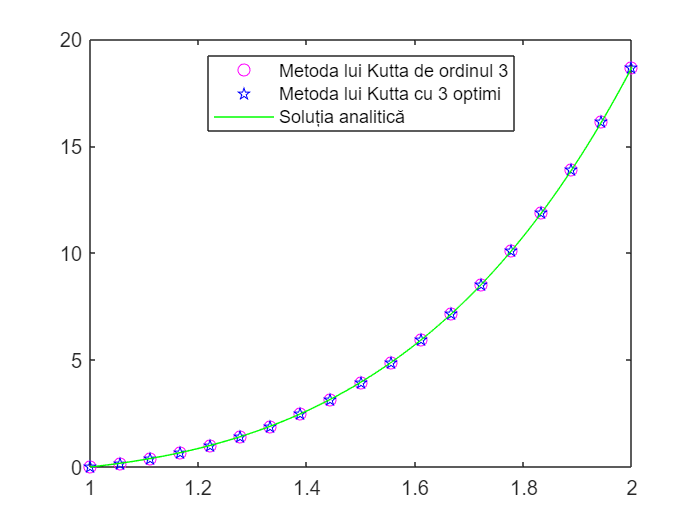

a = 1; b = 2; N = 19; ya = 0;
f = @(t, y) 2 / t * y + t^2 * exp(t);
sol_ex = @(x) x.^2 .* (exp(x) - exp(1));
t = linspace(a, b);
[t_kt, y_kt] = kutta(a, b, f, ya, N);
[t_k38, y_k38]= kuttaThreeEights(a, b, f, ya, N);
plot(t_kt, y_kt, 'mo')
hold on
plot(t_k38, y_k38, 'bp')
plot(t, sol_ex(t), 'g')
legend("Metoda lui Kutta de ordinul 3","Metoda lui Kutta cu 3 optimi","Soluția analitică",Location="best")
hold off

err_kutta = max(abs(y_kt - sol_ex(t_kt)'));
fprintf('Eroarea metodei lui Kutta este %f. \n', err_kutta)

Eroarea metodei lui Kutta este 0.001339. 


err_kutta38=max(abs(y_k38 - sol_ex(t_k38)'));
fprintf('Eroarea metodei lui Kutta cu 3 optimi este %f. \n', err_kutta38)

Eroarea metodei lui Kutta cu 3 optimi este 0.011836. 


## Problema 2

Scrieți ecuația sub formă de sistem și rezolvați folosind metoda lui Heun și o metodă de tip Runge-Kutta de ordin 4:

$\frac{d^2 \theta }{{\textrm{dt}}^2 }+\frac{g}{L}\sin \theta =0,\theta \left(0\right)=0,\frac{d\theta }{\textrm{dt}}\left(0\right)=0\ldotp 1$.

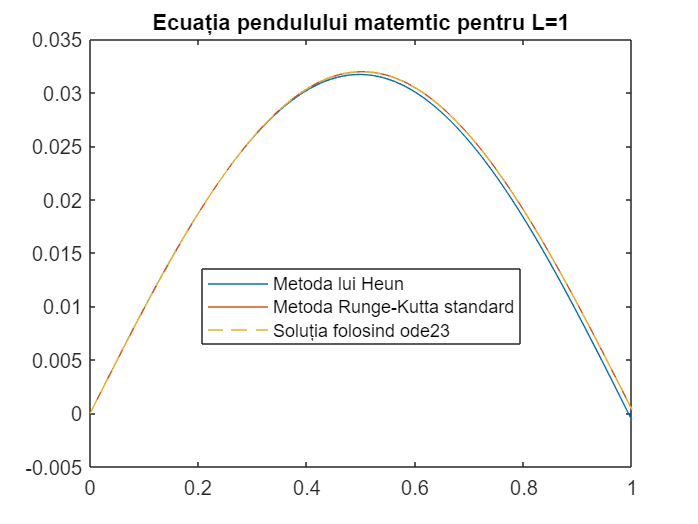

g = 9.8; L = 1; a = 0; b = 1; N = 1000;
t = linspace(0, 1, N);
ya = 0;
ya1 = 0.1;
initval = [ya ya1];
f = @(t,y) -g / L * sin(y);
[t_h, y_h] = heunODE2(a, b, f, ya, ya1, N);
plot(t_h, y_h)
hold on
[t_rk, y_rk] = standardRungeKutta4ODE2(a, b, f, ya, ya1, N);
plot(t_rk, y_rk)
[t, s] = ode23('pendul', t, initval);
plot(t,s(:,1),'--')
legend("Metoda lui Heun","Metoda Runge-Kutta standard","Soluția folosind ode23",Location="best")
title("Ecuația pendulului matemtic pentru L=1")

err_heun = max(abs(y_h - s(:,1)));
fprintf('Eroarea metodei lui Heun este %f. \n', err_heun)

Eroarea metodei lui Heun este 0.000988. 


err_rk = max(abs(y_rk - s(:,1)));
fprintf('Eroarea metodei lui Runge-Kutta standard este %f. \n', err_rk)

Eroarea metodei lui Runge-Kutta standard este 0.000031. 


## Funcții utilizate

### kutta

function [x,y]=kutta(a,b,f,ya,N)
    h=(b-a)/(N-1);
    y(1,:)=ya;
    t=a:h:b;
    x=t;
    for i=2:N
        K1=feval(f,t(i-1),y(i-1));
        K2=feval(f,t(i-1)+0.5*h,y(i-1)+0.5*h*K1);
        K3=feval(f,t(i-1)+h,y(i-1)-h*K1+2*h*K2);
        y(i,:)=y(i-1,:)+h/6*(K1+4*K2+K3);
    end
end

### kuttaThreeEights

function [x,y]=kuttaThreeEights(a,b,f,ya,N)
    h=(b-a)/(N-1);
    y(1,:)=ya;
    t=a:h:b;
    x=t;
    for i=2:N
        K1=feval(f,t(i-1),y(i-1));
        K2=feval(f,t(i-1)+1/3*h,y(i-1)+1/3*h*K1);
        K3=feval(f,t(i-1)+2/3*h,y(i-1)+2/3*h*K2);
        K4=feval(f,t(i-1)+h,y(i-1)+h*K1-h*K2+h*K3);
        y(i,:)=y(i-1,:)+h/8*(K1+3*K2+3*K3+K4);
    end
end

### heunODE2

function [x,y]=heunODE2(a,b,f,ya,y1a,N)
    h=(b-a)/(N-1);
    y(1,:)=ya;
    y1(1,:)=y1a;
    t=a:h:b;
    x=t;
    g=@(t,y,y1)[y1,f(t,y)];
    for i=2:N
        K1=feval(g,t(i-1),y(i-1),y1(i-1));
        K2=feval(g,t(i-1)+h,y(i-1)+h,y1(i-1)+h);
        y1(i,:)=y1(i-1,:)+0.5*h*(K1(2)+K2(2));
        y(i,:)=y(i-1,:)+0.5*h*(K1(1)+K2(1));
    end
end

### pendul

function ds = pendul(t,s)
   ds=zeros(2,1) ;
   ds(1)=s(2) ;
   ds(2)= -9.8*sin(s(1)) ;
end

### standardRungeKutta4ODE2

function [x,y]=standardRungeKutta4ODE2(a,b,f,ya,y1a,N)
h=(b-a)/(N-1);
y(1,:)=ya;
y1(1,:)=y1a;
t=a:h:b;
x=t;
g=@(t,y,y1)[y1,f(t,y)];
for i=2:N
   K1=feval(g,t(i-1),y(i-1),y1(i-1));
   K2=feval(g,t(i-1)+0.5*h,y(i-1)+0.5*h*K1(1),y1(i-1)+0.5*h*K1(2));
   K3=feval(g,t(i-1)+0.5*h,y(i-1)+0.5*h*K2(1),y1(i-1)+0.5*h*K2(2));
   K4=feval(g,t(i-1)+h,y(i-1)+h*K3(1),y1(i-1)+h*K3(2));
   y1(i,:)=y1(i-1,:)+h/6*(K1(2)+2*K2(2)+2*K3(2)+K4(2));
   y(i,:)=y(i-1,:)+h/6*(K1(1)+2*K2(1)+2*K3(1)+K4(1));
end
end